%steps from previous parts that are needed to solve this part are put
%together in a function "match_keypoints(I,I_t,thresh)" whose variables are
%two image matrices to be matched and the distance ratio threshold
%discussed in "lowe2004". Function "match_keypoints(I,I_t,thresh)" is presented at the end of this part.

## i)

Finding keypoints... 
336 keypoints found. 


Finding keypoints... 
324 keypoints found. 


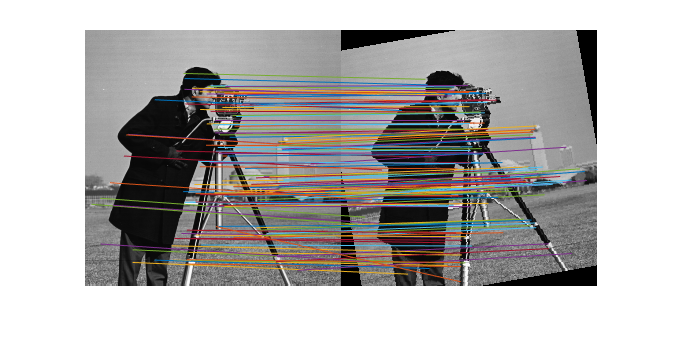

I=double(imread('cameraman.pgm'))/255;
I_t=imrotate(I,10,'crop');
match_keypoints(I,I_t,0.6)

Finding keypoints... 
1233 keypoints found. 


Finding keypoints... 
1085 keypoints found. 


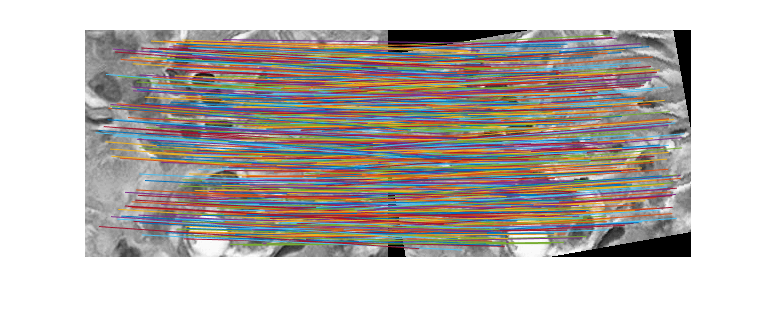


I=double(imread('hestain.pgm'))/255;
I_t=imrotate(I,10,'crop');
match_keypoints(I,I_t,0.6)

Finding keypoints... 
28 keypoints found. 


Finding keypoints... 
221 keypoints found. 


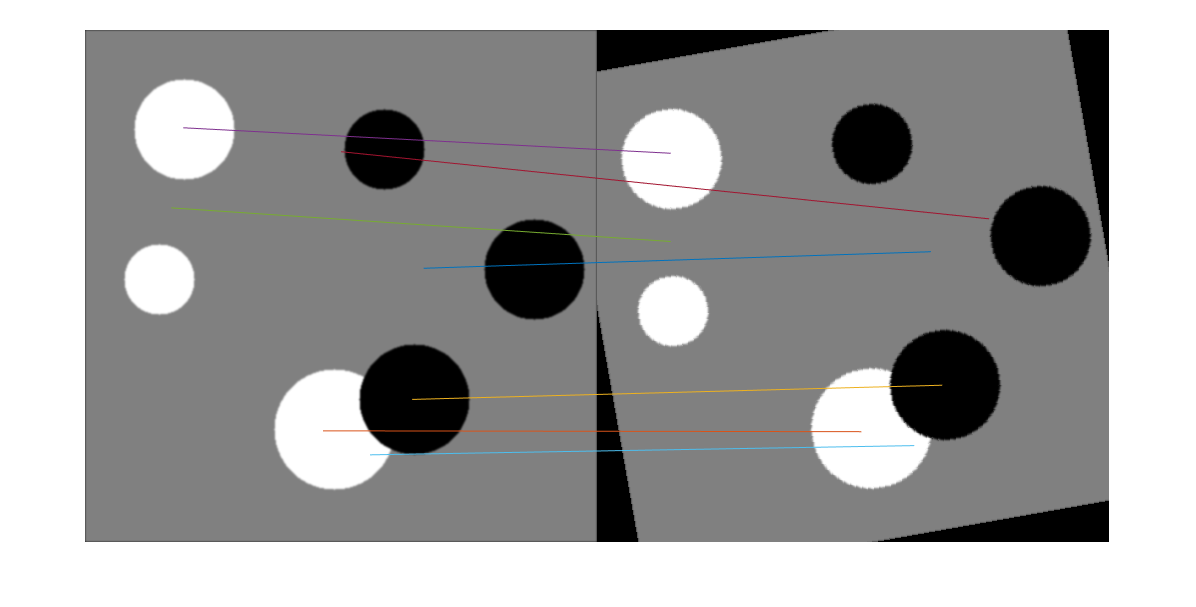


I=double(imread('circlesBrightDark.pgm'))/255;
I_t=imrotate(I,10,'crop');
match_keypoints(I,I_t,0.6)

In case of cameraman image, which is considered to be an ordinary image, by visual inspection it can be concluded that SIFT is working properly, although there are obviously some outliers. Hestain image, on the other hand, is a picture which contains much more details and features, hence there are many more key-point matches, most of which are accurate and, it seems SIFT is working better in this case. Lastly, circlesbrightdark image contains only a few details and as a result, there are only seven keypoint match pairs, out of which only one is inaccurate. Although the accuracy is high, lack of numerous details and key-point matches could cause problems in some cases, knowing that at least three pairs are needed for affine parameters to be calculated.

## ii)

Finding keypoints... 
336 keypoints found. 


Finding keypoints... 
407 keypoints found. 


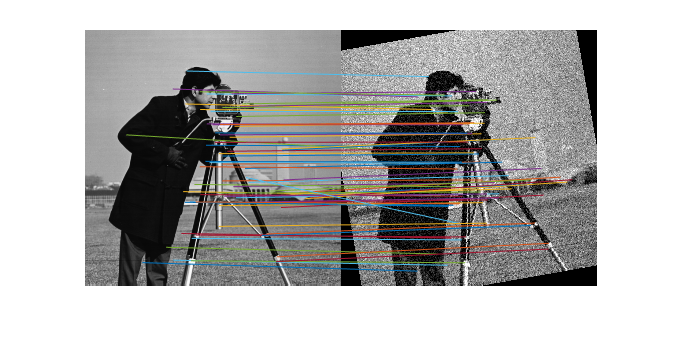

I=double(imread('cameraman.pgm'))/255;
%adding gaussian noise
I1=I+0.1*randn(size(I));
%clipping intensities less than 0 and greater than 1
I1(I1<0)=0;
I1(I1>1)=1;
I_t=imrotate(I1,10,'crop');
match_keypoints(I,I_t,0.6)

Finding keypoints... 
1233 keypoints found. 


Finding keypoints... 
653 keypoints found. 


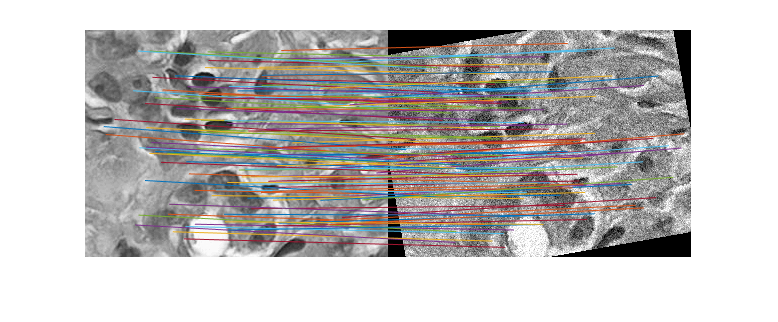


I=double(imread('hestain.pgm'))/255;
I1=I+0.1*randn(size(I));
I1(I1<0)=0;
I1(I1>1)=1;
I_t=imrotate(I1,10,'crop');
match_keypoints(I,I_t,0.6)

Finding keypoints... 
28 keypoints found. 


Finding keypoints... 
649 keypoints found. 


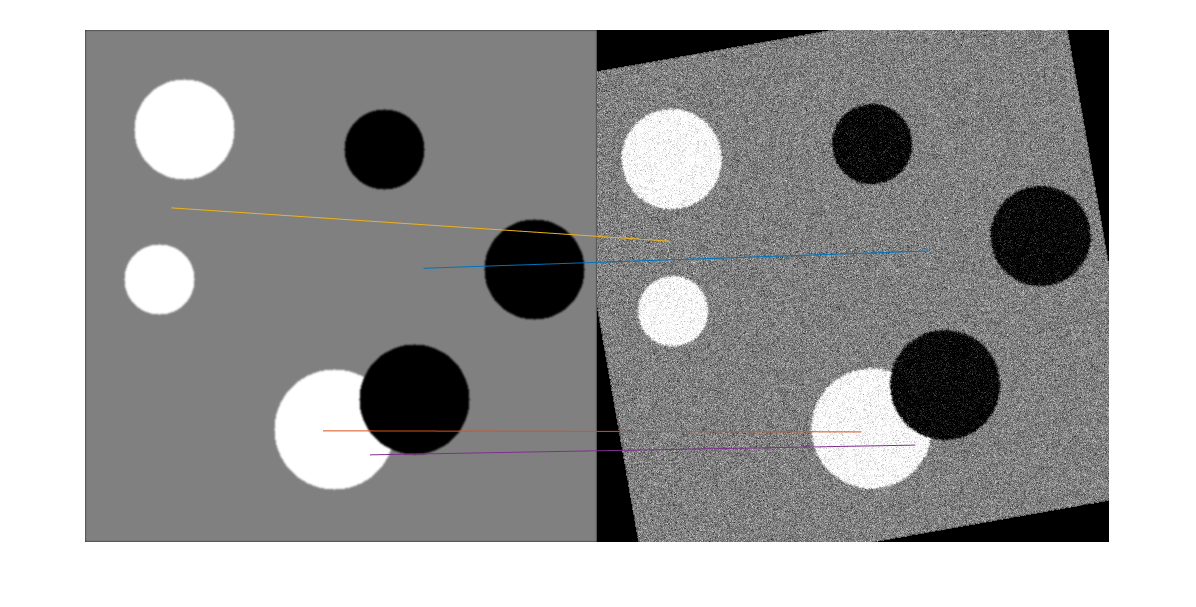


I=double(imread('circlesBrightDark.pgm'))/255;
I1=I+0.1*randn(size(I));
I1(I1<0)=0;
I1(I1>1)=1;
I_t=imrotate(I1,10,'crop');
match_keypoints(I,I_t,0.6)

In this part, the number of key-point matches has been reduced in all three cases. Due to random nature of the noise that is added in this part, the number of matching key-points changes every time that the code is ran. Again, most matches are seen in Hestain image and least matches (still more than three pairs) is in circlesbrightdark image. Visual inspection suggests good performance in all three cases.

## iii)

Finding keypoints... 
336 keypoints found. 


Finding keypoints... 
123 keypoints found. 


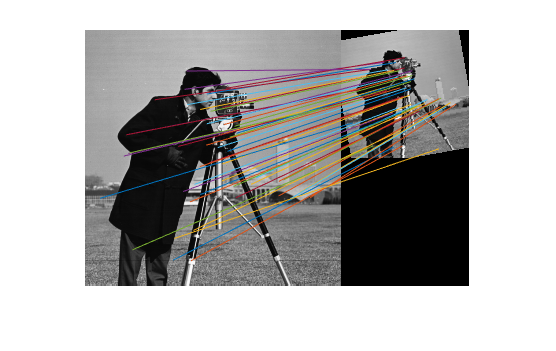

I=double(imread('cameraman.pgm'))/255;
I1=imresize(I,size(I)/2);
I_t=imrotate(I1,10,'crop');
match_keypoints(I,I_t,0.6)

Finding keypoints... 
1233 keypoints found. 


Finding keypoints... 
266 keypoints found. 


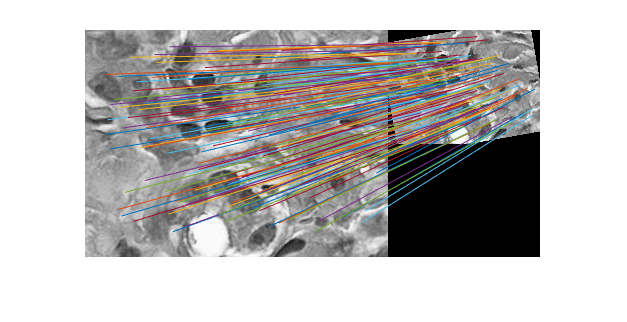


I=double(imread('hestain.pgm'))/255;
I1=imresize(I,size(I)/2);
I_t=imrotate(I1,10,'crop');
match_keypoints(I,I_t,0.6)

Finding keypoints... 
28 keypoints found. 


Finding keypoints... 
143 keypoints found. 


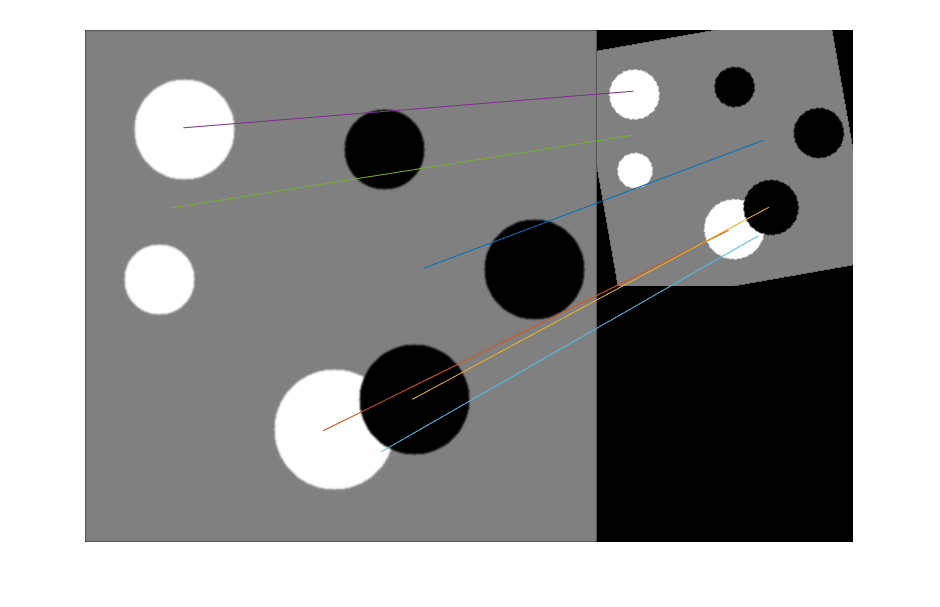


I=double(imread('circlesBrightDark.pgm'))/255;
I1=imresize(I,size(I)/2);
I_t=imrotate(I1,10,'crop');
match_keypoints(I,I_t,0.6)

Unlike last two parts, in which connecting lines were, to some extent, parallel, connecting lines seem to be converging toward a focal point (or area). Number of detected matches in these cases are comperable to those of the second part. Visual inspection shows acceptable performance of the SIFT algorithm. 

## iv)

Finding keypoints... 
336 keypoints found. 


Finding keypoints... 
1233 keypoints found. 


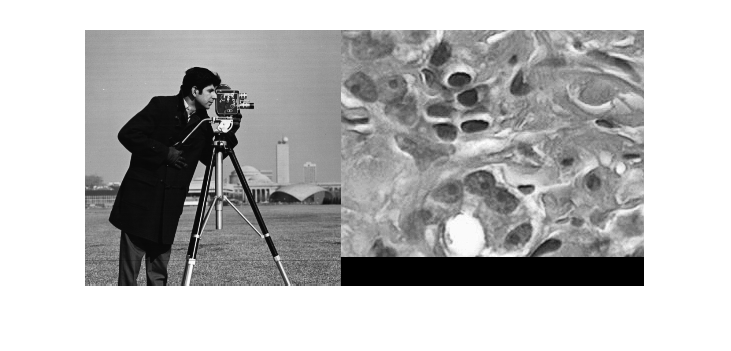

I=double(imread('cameraman.pgm'))/255;
I_t=double(imread('hestain.pgm'))/255;
match_keypoints(I,I_t,0.6)

By using 0.6 as the distance ratio threshold, no matching key-point pair is detected. And it is a good feature to detect non-related images.

## v)

Finding keypoints... 
336 keypoints found. 


Finding keypoints... 
324 keypoints found. 


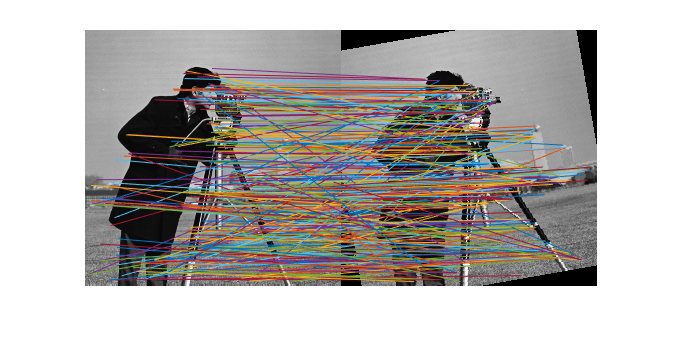

I=double(imread('cameraman.pgm'))/255;
I_t=imrotate(I,10,'crop');
match_keypoints(I,I_t,1)

Using 1.00 as distance ratio threshold in this part caused the code to consider all the matching candidates as matching key-points. As it was expected, the lines are not aligned like before because many outlier matches are present now.

## Function:

function match_keypoints(I,I_t,thresh)
imwrite(I,'I.pgm');
imwrite(I_t,'I_t.pgm');
system('siftDemoV4\siftWin32 <I.pgm>I.key');
system('siftDemoV4\siftWin32 <I_t.pgm>I_t.key');
[xyso,F]=create_feature_matrices('I.key');
[xyso_t,F_t]=create_feature_matrices('I_t.key');
sbs=zeros(max(size(I,1),size(I_t,1)),size(I,2)+size(I_t,2));
sbs(1:size(I,1),1:size(I,2))=I;
sbs(1:size(I_t,1),size(I,2)+1:end)=I_t;
D=pairwise_distance(F,F_t);
P=paired_keypoints(D,thresh);
figure,
imshow(sbs)
hold on
for i=1:numel(P)
   if P(i)~=0
      plot([xyso(i,2),xyso_t(P(i),2)+size(I,2)],[xyso(i,1),xyso_t(P(i),1)])
   end
end
end